Colin Keenan

ECE 5470

2-24-2020

# Homework 4

1.  Laplacian Enhancement

## Write program to implement the Laplacian enhancement technique described in Lecture Note 4. Use the mask shown in Slide 4-63 (c and d) on Fig-1a.jpg

clear

fprintf("Question 1, Part A:")

Question 1, Part A:

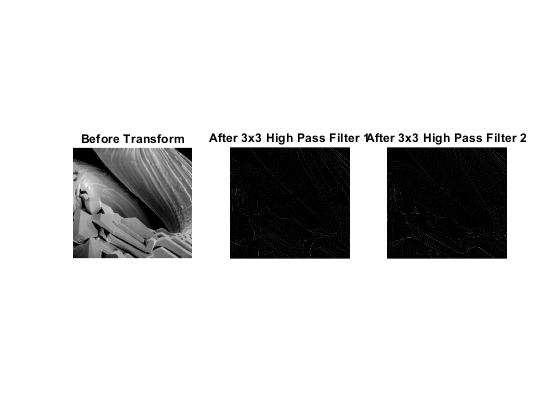


file = 'Fig4-1a.jpg';
image = imread(file);
image_double = im2double(image);

image_mod_3x3_hp = zeros(size(image_double));
image_mod_3x3_hp_inv = zeros(size(image_double));


mask_3x3_hp = [[-1 -1 -1]
               [-1  8 -1]
               [-1 -1 -1]];

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3_hp;
        image_mod_3x3_hp(i,j) = sum(masked,"all");
    end
end
        
mask_3x3_hp_inv = [[1  1  1]
                   [1 -8  1]
                   [1  1  1]];
               
for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3_hp_inv;
        image_mod_3x3_hp_inv(i,j) = sum(masked,"all");
    end
end

figure();
subplot(1,3,1)
imshow(image);
title("Before Transform");
subplot(1,3,2)
imshow(image_mod_3x3_hp);
title("After 3x3 High Pass Filter 1");
subplot(1,3,3)
imshow(image_mod_3x3_hp_inv);
title("After 3x3 High Pass Filter 2");

## Write program to implement the Laplacian enhancement technique described in Lecture Note 4. Use the mask shown in Slide 4-63 (c and d) on Fig-1b.jpg

clear

fprintf("Question 1, Part B:")

Question 1, Part B:

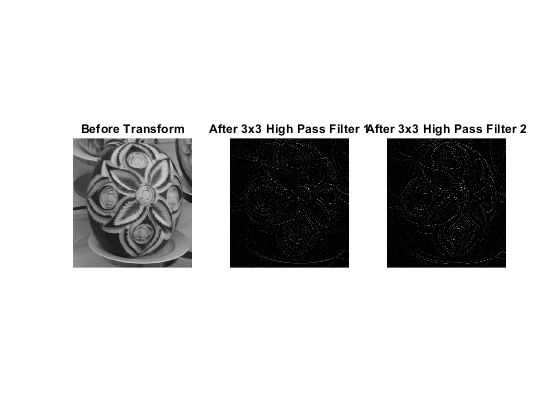


file = 'Fig4-1b.jpg';
image = imread(file);
image_double = im2double(image);

image_mod_3x3_hp = zeros(size(image_double));
image_mod_3x3_hp_inv = zeros(size(image_double));


mask_3x3_hp = [[-1 -1 -1]
               [-1  8 -1]
               [-1 -1 -1]];

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3_hp;
        image_mod_3x3_hp(i,j) = sum(masked,"all");
    end
end
        
mask_3x3_hp_inv = [[1  1  1]
                   [1 -8  1]
                   [1  1  1]];
               
for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked = frame_3x3 .* mask_3x3_hp_inv;
        image_mod_3x3_hp_inv(i,j) = sum(masked,"all");
    end
end

figure();
subplot(1,3,1)
imshow(image);
title("Before Transform");
subplot(1,3,2)
imshow(image_mod_3x3_hp);
title("After 3x3 High Pass Filter 1");
subplot(1,3,3)
imshow(image_mod_3x3_hp_inv);
title("After 3x3 High Pass Filter 2");

2. Unsharpmasking and Highboost Filtering

## Perform on Fig4-3.tif

clear

fprintf("Question 2:")

Question 2:

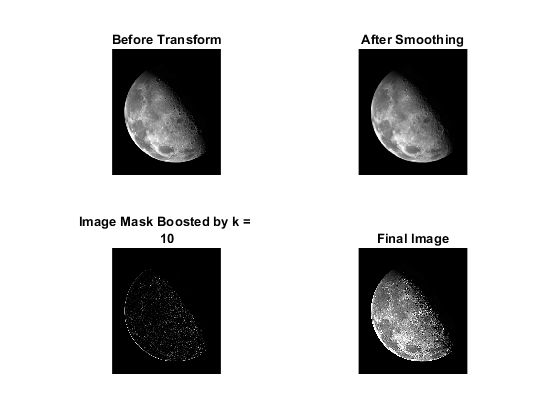


file = 'Fig4-2.tif';
image = imread(file);
image_double = im2double(image);

image_mod_3x3_smooth = zeros(size(image_double));

mask_3x3 = [[1 1 1]
            [1 1 1]
            [1 1 1]];
weight_3x3 = sum(sum(mask_3x3));

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked_3x3 = frame_3x3 .* mask_3x3;
        new_level = sum(sum(masked_3x3)) / weight_3x3;
        image_mod_3x3_smooth(i,j) = new_level;
    end
end

image_mask = image_double - image_mod_3x3_smooth;

k = 10;
image_mask_boosted = k .* image_mask;
image_mod = image_double + image_mask_boosted;

figure();
subplot(2,2,1)
imshow(image);
title("Before Transform");
subplot(2,2,2)
imshow(image_mod_3x3_smooth);
title("After Smoothing");
subplot(2,2,3)
imshow(image_mask_boosted);
title(["Image Mask Boosted by k = " num2str(k)]);
subplot(2,2,4)
imshow(image_mod);
title("Final Image");

Explanation: As seen in the final image, the craters and edges of the moon are greatly accentuated due to this effective highpass filter with the highpass part of the filter having a multiplier of x10.

3.  Edge Detection

## Apply Sobel oeprators for edge detection and theshold to present the image in black and white for Fig4-3.tif

clear

fprintf("Question 3:")

Question 3:

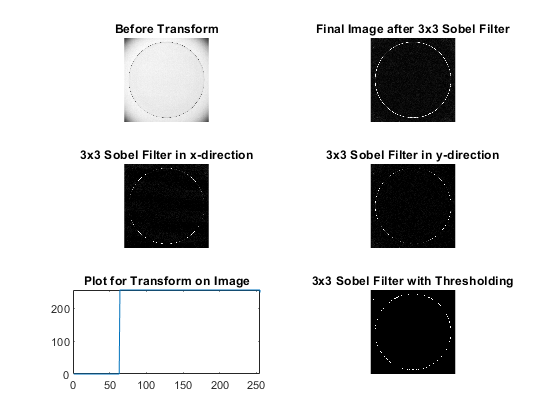


file = 'Fig4-3.tif';
image = imread(file);
image_double = im2double(image);

image_mod_3x3_sobel_x = zeros(size(image_double));
image_mod_3x3_sobel_y = zeros(size(image_double));

mask_3x3_sobel_y = [[-1 -2 -1]
                    [ 0  0  0]
                    [ 1  2  1]];

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked_3x3 = frame_3x3 .* mask_3x3_sobel_y;
        image_mod_3x3_sobel_x(i,j) = sum(masked_3x3,"all");
    end
end
        
mask_3x3_sobel_x = [[-1 0 1]
                    [-2 0 2]
                    [-1 0 1]];

for i = 1+1 : size(image_double,1)-1
    for j = 1+1 : size(image_double,2)-1
        
        frame_3x3 = [[image_double(i-1,j-1) image_double(i-1,j+0) image_double(i-1,j+1)]
                     [image_double(i+0,j-1) image_double(i+0,j+0) image_double(i+0,j+1)]
                     [image_double(i+1,j-1) image_double(i+1,j+0) image_double(i+1,j+1)]];
        masked_3x3 = frame_3x3 .* mask_3x3_sobel_x;
        image_mod_3x3_sobel_y(i,j) = sum(masked_3x3,"all");
    end
end

image_mod_3x3_sobel = sqrt(image_mod_3x3_sobel_x.^2 + image_mod_3x3_sobel_y.^2);

image_mod_3x3_sobel_thresh = zeros(size(image_double));

upper_range = 255/255;
lower_range = 64/255;

transform = 1:256;
for x = 1:256
    if((x >= lower_range*255) && (x <= upper_range*255))
        transform(x) = 255;
    else
        transform(x) = 0;
    end
end

for i = 1:size(image_double,1)
    for j = 1:size(image_double,2)
        r = image_mod_3x3_sobel(i,j);
        if((r >= lower_range) && (r <= upper_range))
            image_mod_3x3_sobel_thresh(i,j) = 1;
        else
            image_mod_3x3_sobel_thresh(i,j) = 0;
        end
    end
end

figure();
subplot(3,2,1)
imshow(image);
title("Before Transform");
subplot(3,2,2)
imshow(image_mod_3x3_sobel);
title("Final Image after 3x3 Sobel Filter");
subplot(3,2,3)
imshow(image_mod_3x3_sobel_x);
title("3x3 Sobel Filter in x-direction");
subplot(3,2,4)
imshow(image_mod_3x3_sobel_y);
title("3x3 Sobel Filter in y-direction");
subplot(3,2,5)
plot(transform);
xlim([0,255]);
ylim([0,255]);
title("Plot for Transform on Image");
subplot(3,2,6)
imshow(image_mod_3x3_sobel_thresh);
title("3x3 Sobel Filter with Thresholding");